## Exam 23 October 2020

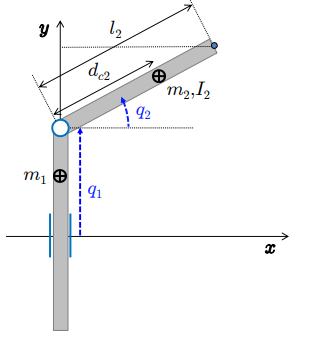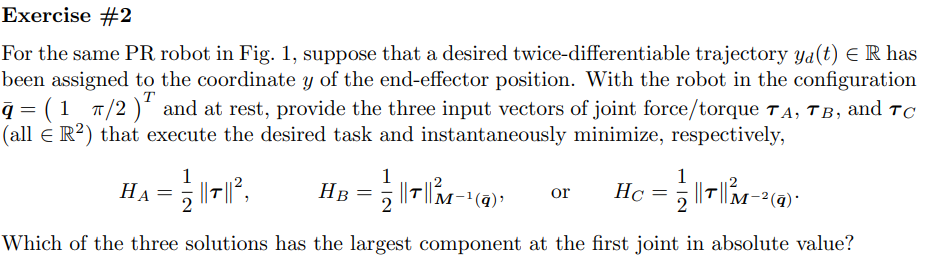

%% Symbolic variables
syms q1 q2 l1 l2 d1 d2 m1 m2 real
syms g0 q1_dot q2_dot I2 real
syms dq1 dq2 r_dot_dot real

dq = [dq1; dq2];

%% Kinetic energy of prismatic joint 1 (translation along y)
T1 = 0.5 * m1 * q1_dot^2;

%% Kinetic energy of rotational joint 2
x2 = d2 * cos(q2);
y2 = q1 + d2 * sin(q2);
vx2 = diff(x2, q1) * q1_dot + diff(x2, q2) * q2_dot;
vy2 = diff(y2, q1) * q1_dot + diff(y2, q2) * q2_dot;
T2 = simplify(0.5*m2*[vx2 vy2 0]*[vx2; vy2; 0;] + 0.5 * I2 * q2_dot^2)

$$T2 = \frac{m_{2}\,{d_{2}}^{2}\,{q_{\dot{2}}}^{2}}{2}+m_{2}\,\cos\left(q_{2}\right)\,d_{2}\,q_{\dot{1}}\,q_{\dot{2}}+\frac{m_{2}\,{q_{\dot{1}}}^{2}}{2}+\frac{I_{2}\,{q_{\dot{2}}}^{2}}{2}$$


%% Total kinetic energy
T = simplify(T1 + T2);

%% Inertia matrix M(q)
M11 = diff(diff(T, q1_dot), q1_dot);
M12 = diff(diff(T, q1_dot), q2_dot);
M21 = diff(diff(T, q2_dot), q1_dot);
M22 = diff(diff(T, q2_dot), q2_dot);
M = simplify([M11, M12; M21, M22])

$$M = \left(\begin{array}{cc} m_{1}+m_{2} & d_{2}\,m_{2}\,\cos\left(q_{2}\right)\\ d_{2}\,m_{2}\,\cos\left(q_{2}\right) & m_{2}\,{d_{2}}^{2}+I_{2} \end{array}\right)$$


%% Coriolis vector n(q, dq)
q = [q1; q2];
C = sym(zeros(2, 2));
for i = 1:2
    for j = 1:2
        tmp = 0;
        for k = 1:2
            tmp = tmp + 0.5 * ( ...
                diff(M(i,j), q(k)) + ...
                diff(M(i,k), q(j)) - ...
                diff(M(k,j), q(i)) ) * dq(k);
        end
        C(i,j) = simplify(tmp);
    end
end
n_q = simplify(C*dq)  % no gravity

$$n\_q = \left(\begin{array}{c} -d_{2}\,{{\mathrm{dq}}_{2}}^{2}\,m_{2}\,\sin\left(q_{2}\right)\\ 0 \end{array}\right)$$


%% Task Jacobian (y-direction of end-effector)
y = q1 + l2 * sin(q2);
J = jacobian(y, [q1 q2])  % 1x2 Jacobian

$$J = \left(\begin{array}{cc} 1 & l_{2}\,\cos\left(q_{2}\right) \end{array}\right)$$


%% Compute the residual vector
Minv = subs(simplify(inv(M)),[q1, q2, dq1, dq2], [1, pi/2,0,0])

$$Minv = \left(\begin{array}{cc} \frac{m_{2}\,{d_{2}}^{2}+I_{2}}{{d_{2}}^{2}\,{m_{2}}^{2}+m_{1}\,{d_{2}}^{2}\,m_{2}+I_{2}\,m_{2}+I_{2}\,m_{1}} & 0\\ 0 & \frac{m_{1}+m_{2}}{{d_{2}}^{2}\,{m_{2}}^{2}+m_{1}\,{d_{2}}^{2}\,m_{2}+I_{2}\,m_{2}+I_{2}\,m_{1}} \end{array}\right)$$

J_dot = [0 -l2*dq2*sin(q2)]

$$J\_dot = \left(\begin{array}{cc} 0 & -{\mathrm{dq}}_{2}\,l_{2}\,\sin\left(q_{2}\right) \end{array}\right)$$

dJ_dq = subs(J_dot*[dq1; dq2;],[q1, q2, dq1, dq2], [1, pi/2,0,0]) % scalar

$$dJ\_dq = 0$$

pro = J*Minv*n_q

$$pro = -\frac{d_{2}\,{{\mathrm{dq}}_{2}}^{2}\,m_{2}\,\sin\left(q_{2}\right)\,\left(m_{2}\,{d_{2}}^{2}+I_{2}\right)}{{d_{2}}^{2}\,{m_{2}}^{2}+m_{1}\,{d_{2}}^{2}\,m_{2}+I_{2}\,m_{2}+I_{2}\,m_{1}}$$

residual = subs(r_dot_dot - dJ_dq + pro, [q1, q2, dq1, dq2], [1, pi/2,0,0])

$$residual = \dot{\dot{r}}$$

re_subs = subs(residual, [q1, q2, dq1, dq2], [1, pi/2,0,0])

$$re\_subs = \dot{\dot{r}}$$

pro_2 = subs(pinv(J * Minv), [q1, q2, dq1, dq2], [1, pi/2,0,0])

$$pro\_2 = \left(\begin{array}{c} \frac{{d_{2}}^{2}\,{m_{2}}^{2}+m_{1}\,{d_{2}}^{2}\,m_{2}+I_{2}\,m_{2}+I_{2}\,m_{1}}{m_{2}\,{d_{2}}^{2}+I_{2}}\\ 0 \end{array}\right)$$


%% Final torques 
% τ_1 (minimum torque norm)
tau_A = simplify(pro_2 * residual);

% τ_2 (squared inverse inertia weighted torque norm)
tau_B = simplify(M * pinv(J) * residual);

% τ_3 (inverse inertia weighted torque norm)
tau_C = simplify(J.' * inv(J * Minv * J.') * residual);

%% Manual substitution with values

tau_A_eval = subs(tau_A, [q1, q2, dq1, dq2], [1, pi/2,0,0]);
tau_B_eval = subs(tau_B, [q1, q2, dq1, dq2], [1, pi/2,0,0]);
tau_C_eval = subs(tau_C, [q1, q2, dq1, dq2], [1, pi/2,0,0]);

%% Display results
disp("tau_A ="); disp(tau_A_eval);

tau_A =


$$\left(\begin{array}{c} \dot{\dot{r}}\,\left(m_{1}+m_{2}\right)\\ 0 \end{array}\right)$$

disp("tau_B ="); disp(tau_B_eval);

tau_B =


$$\left(\begin{array}{c} \dot{\dot{r}}\,\left(m_{1}+m_{2}\right)\\ 0 \end{array}\right)$$

disp("tau_C ="); disp(tau_C_eval);

tau_C =


$$\left(\begin{array}{c} \dot{\dot{r}}\,\left(m_{1}+m_{2}\right)\\ 0 \end{array}\right)$$